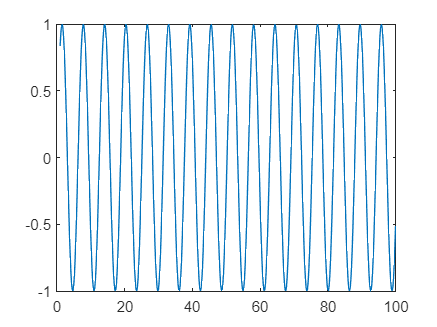

xTrain = 1:0.2:100;
yTrain = sin(xTrain);
plot(xTrain, yTrain)

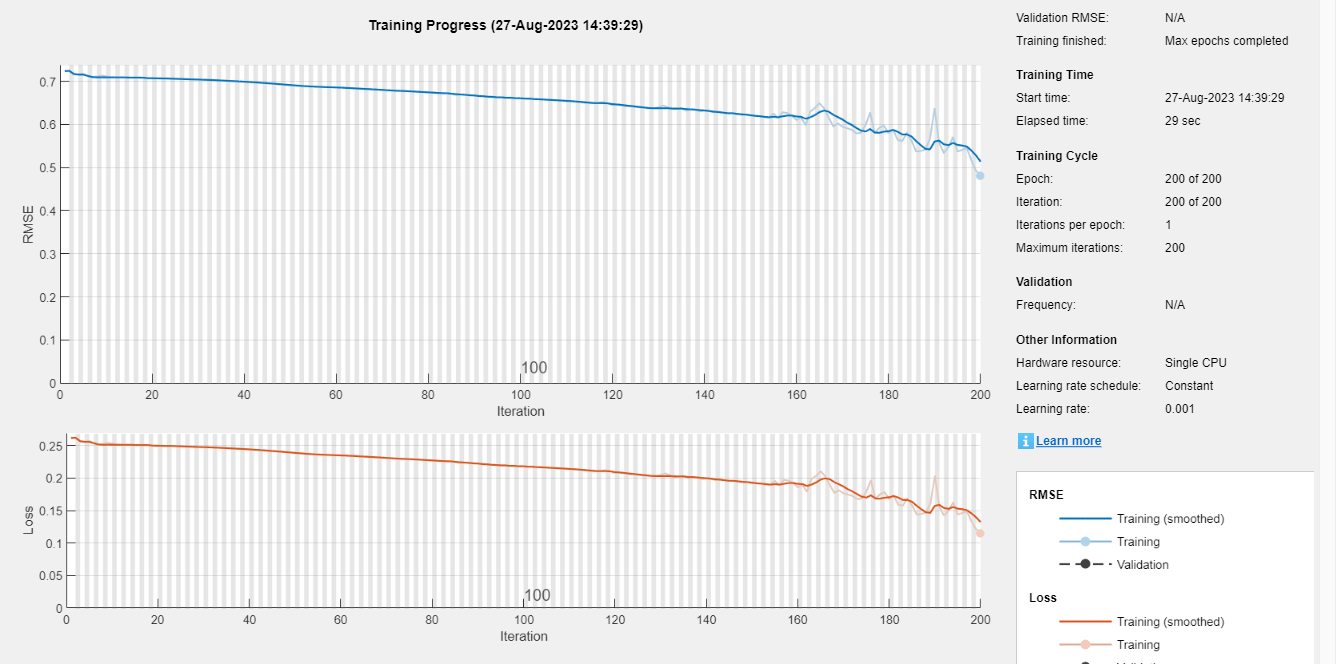

layers = [
    sequenceInputLayer(1)
    lstmLayer(128)
    fullyConnectedLayer(1)
    regressionLayer];
options = trainingOptions("adam", ...
    MaxEpochs=200, ...
    SequencePaddingDirection="left", ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=0);

net = trainNetwork(xTrain,yTrain,layers,options);

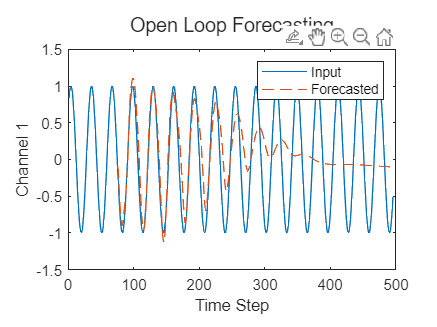

net = resetState(net);
offset = 75;
[net,~] = predictAndUpdateState(net,xTrain(:,1:offset));

numTimeSteps = size(xTrain,2);
numPredictionTimeSteps = numTimeSteps - offset;
Y = zeros(1,numPredictionTimeSteps);

for t = 1:numPredictionTimeSteps
    Xt = xTrain(:,offset+t);
    [net,Y(:,t)] = predictAndUpdateState(net,Xt);
end

figure
t = tiledlayout(1,1);
title(t,"Open Loop Forecasting")

for i = 1:1
    nexttile
    plot(yTrain(i,:))
    hold on
    plot(offset:numTimeSteps,[yTrain(i,offset) Y(i,:)],'--')
    ylabel("Channel " + i)
end

xlabel("Time Step")
nexttile(1)
legend(["Input" "Forecasted"])